# Controllo di un elicottero

L'obiettivo del lavoro è l'applicazione di tre diverse tecniche di progetto per il controllo di hovering di un elicottero Yamaha R-MAX. Lo Yamaha R-MAX è un UAV alimentato a benzina comandato in linea di vista dall'utente tramite un telecomando. È stato progettato principalmente per essere utilizzato in ambito agricolo.

Il modello matematico di un elicottero è chiaramente non lineare e le equazioni da utilizzare cambiano in base al regime di volo. In questo elaborato ci si concentrerà sul volo a bassa velocità, il cui modello può essere linearizzato e, con le opportune semplificazioni, ridotto ad un sistema di ordine 13. 

Le grandezze di controllo sono:

- Lateral Cyclic: permette di inclinare il rotore principale in modo da spostare il vettore di spinta lateralmente consentendo all'elicottero di muoversi in tale direzione.

- Longitudinal Cyclic: come il lateral cyclic, permette di muoversi longitudinalmente.

- Rudder: permette di controllare la direzione verso cui punta il muso dell'elicottero. Il rudder funziona modificando l'angolo di incidenza del rotore di coda, aumentando o diminuendone la spinta nella direzione desiderata.

- Collective pitch: consente di variare l'angolo di incidenza delle pale del rotore  principale contemporaneamente.  Aumentando il collective pitch, si aumenta la spinta verticale e  l'elicottero sale, mentre diminuendolo si riduce la spinta e l'elicottero scende.

Le grandezze di controllo variano tra -1 ed 1 (adimensionali). Il regime di validità del modello è tale per cui se il controllo funziona bene, le grandezze di controllo dovrebbero sempre rimanere ben lontane dai valori limite. Negli schemi di simulazione Simulink, sono stati comunque inseriti i blocchi di saturazione che simulano il limite fisico degli attuatori.

Il tempo di assestamento deve essere di circa 5 secondi. La sovraelongazione deve essere bassa (massimo 20%). In questo contesto, una sovraelongazione più bassa è preferibile anche se ciò comporta un leggero aumento del tempo di assestamento.

Le uscite del modello sono le tre velocità traslazionali e la velocità di rotazione intorno all'asse verticale.

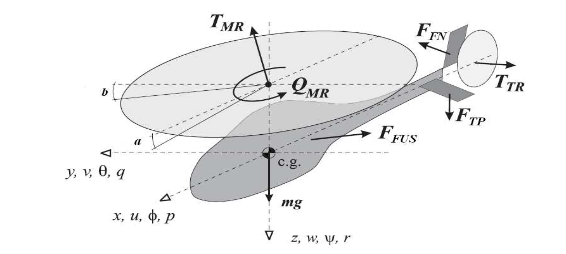

MATRICIONI

Le variabili di stato sono rispettivamente: 'u','v','roll rate','pitch rate','roll','pitch','flapping a','flapping b','w','yaw rate','gyroscope yaw rate','paddle c', 'paddle d'. Tutte le grandezze sono espresse nelle unità di misura del Sistema Internazionale.

### Modello

clear all
load('Elicottero.mat')

states = {'u','v','roll rate','pitch rate','roll','pitch','flapping a','flapping b','w','yaw rate','gyroscope yaw rate','paddle c', 'paddle d'};
inputs = {'Lateral cyclic [-1, 1]', 'Longitudinal cyclic [-1, 1]', 'Rudder [-1, 1]', 'Collective pitch [-1, 1]'};
outputs = {'u', 'v', 'w','gyroscope yaw rate'};
C = zeros(4,13);
C(1,strcmp(states, 'u')) = 1;
C(2,strcmp(states, 'v')) = 1;
C(3,strcmp(states, 'w')) = 1;
C(4,strcmp(states, 'gyroscope yaw rate')) = 1;

D = zeros(4,4);
sys = ss(A,B,C,D);

s = tf('s');
%matrice di trasferimento
G = tf(sys);
%bode(G), figure, step(G)

Per prima cosa è necessario controllare le proprietà di controllabilità ed osservabilità del sistema. Dato che gli elementi della matrice di controllabilità e di osservabilità spaziano in un range molto grande (alcuni elementi sono minori di uno, altri sono maggiori di ${10}^{12}$), la tolleranza di default utilizzata da Matlab porta a conclusioni errate. Specificando un'opportuna tolleranza si vede che il sistema è completamente controllabile e completamente osservabile. 

Ctr = ctrb(A,B); r_ctr = rank(Ctr,1e-6)

r_ctr = 13

Obs = obsv(A,C); r_obs = rank(Obs,1e-6)

r_obs = 13

## Assegnamento degli autovalori

La prima tecnica di progetto consiste nell'assegnamento degli autovalori. Sei poli del sistema vengono scelti con il metodo ITAE: data una pulsazione $\omega_n$ sono i poli che minimizzano $\int_0^{+\infty \;} t|e\left(t\right)|\textrm{dt}$ che garantiscono poche oscillazioni con una sovraelongazione relativamente piccola. La pulsazione $\omega_n$ viene scelta per tentativi sulla base del tempo di assestamento desiderato. I restanti poli devono essere scelti non troppo a sinistra per evitare un controllo troppo grande o troppo nervoso, non troppo vicini ai poli assegnati con itae per non fargli perdere la dominanza. Un buon trade-off è stato trovato prendendoli reali e distanziandoli rispettivamente di uno verso sinistra.

omega_n_itae = 1.7;

p_itae = itae(6,omega_n_itae);

for i=7:13
    p_itae = [p_itae real(p_itae(i-1))-1];
end

Poli assegnati:

disp(p_itae')

  -0.5268 + 2.1477i
  -0.5268 - 2.1477i
  -0.9869 + 1.3308i
  -0.9869 - 1.3308i
  -1.2489 + 0.4883i
  -1.2489 - 0.4883i
  -2.2489 + 0.0000i
  -3.2489 + 0.0000i
  -4.2489 + 0.0000i
  -5.2489 + 0.0000i
  -6.2489 + 0.0000i
  -7.2489 + 0.0000i
  -8.2489 + 0.0000i



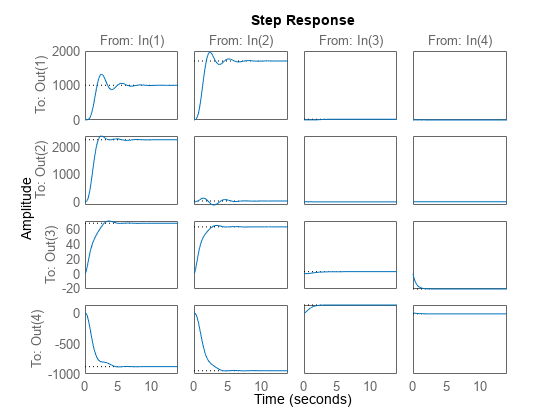

ans = 1.0e+03 *

    1.0043    1.7099    0.0187   -0.0026
    2.2615    0.0263   -0.0043    0.0004
    0.0681    0.0631    0.0027   -0.0207
   -0.8790   -0.9459    0.1326   -0.0124


K_itae = place(A,B,p_itae);

CC_itae = ss(A-B*K_itae,B,C,D);

step(CC_itae), dcgain(CC_itae)

### Azione integrale

Ovviamente l'assegnamento degli autovalori non permette di ottenere errore a regime nullo. Per garantire questa specifica è necessario introdurre 4 integratori che vanno ad integrare l'errore dell'uscita rispetto al riferimento. Si considera quindi il sistema aumentato che deve essere completamente controllabile:

Aint = [A  zeros(13,4);
        -C zeros(4,4)];
Bint = [B; -D];
Cint = [C, zeros(4,4)];
Dint = D;

Ctr_int = ctrb(Aint,Bint); r_ctr_int = rank(Ctr_int,1e-6)

r_ctr_int = 17

La matrice di controllabilità ha rango pieno, quindi la risposta è affermativa. A questo punto è necessario assegnare i 17 poli del sistema aumentato. I primi 13 sono quelli scelti in precedenza, i successivi vengono scelti facendo le stesse considerazioni fatte prima.

p_int = [p_itae';
         p_itae(end)-0.5;
         p_itae(end)-1;
         p_itae(end)-1.5;
         p_itae(end)-2];
K_int = place(Aint,Bint,p_int);

La K ottennuta con il comando place è costituita da 17 elementi. Per come sono state costruite le matrici dell'impianto aumentato, i primi 13 elementi sono relativi alla retroazione di stato, gli ultimi 4 sono le costanti moltiplicative degli integratori.

K_s = K_int(:,1:13);
K_i = K_int(:,14:17);

### Osservatore

Per il principio di separazione è possibile progettare direttamente l'osservatore. I poli dell'osservatore devono essere scelti sufficientemente a sinistra da consentire convergenza rapida dell'errore di stima, ricordando però che un osservatore troppo veloce aumenta la banda del sistema amplificando il rumore di misura.

p_obs = real(p_itae)-10;
L = place(A',C',p_obs)';

Aobs = (A-L*C);
Bobs = [B - L*D, L];
Cobs = eye(13);
Dobs = zeros(13,8);

Per verificare il funzionamento della retroazione di stato con azione integrale si pone la condizione iniziale dell'osservatore uguale alla condizione iniziale del sistema. In questo modo è come se l'osservatore non ci fosse.

I grafici mostrano la risposta ad un rifermiento di $1\;m/s$ lungo x e, dopo 3 secondi anche un riferimento di $0\ldotp 5\;m/s$ lungo la direzione verticale. Praticamente si sta chiedendo all'elicottero di muoversi in avanti e contemporaneamente scendere dopo 5 secondi mantenendo nulle le velocità  laterali e di rotazione intorno all'asse verticale.

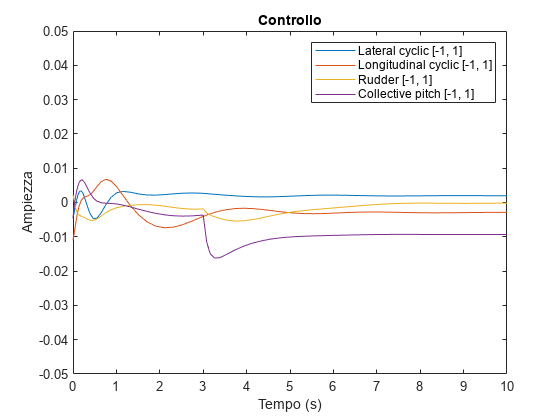

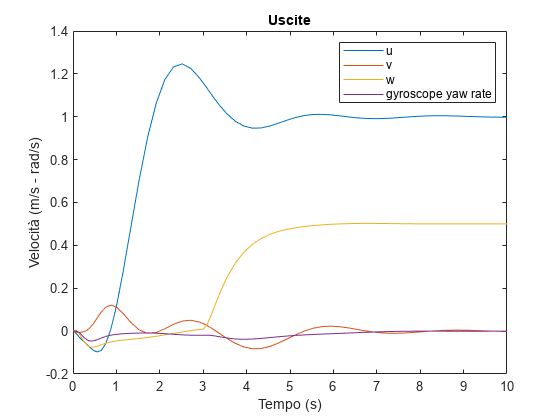

x0_obs = 0;
eig_out = sim('autovalori_sim.slx');
plotyu(eig_out,'ulim',[-0.05,0.05],'ylegend',outputs,'ulegend',inputs)

Per verificare il funzionamento dell'osservatore, si può ripetere la simulazione facendolo partire da uno stato iniziale diverso da quello del sistema. Al solo scopo di visualizzare l'errore di stima, alla matrice C del processo è stata aggiunta una matrice identità che permette di visualizzarne lo stato.

x0_obs = rand(13,1)*0.005-0.0025;
eig_out_obs = sim('autovalori_sim.slx');
plotyu(eig_out_obs,'ulim',[-0.05,0.05],'ylegend',outputs,'ulegend',inputs,'un',1:4,'yn',1:4)

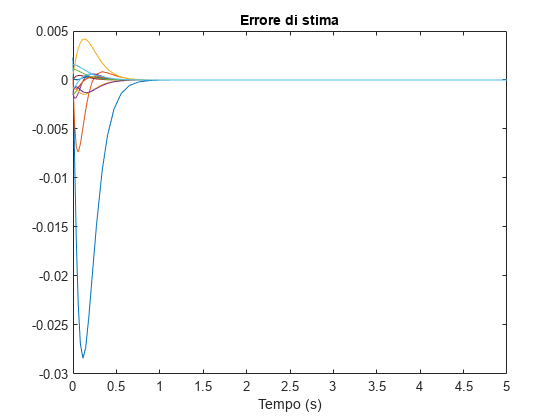

plot(eig_out_obs.e.time,eig_out_obs.e.signals.values);
title('Errore di stima')
xlabel('Tempo (s)')
xlim([0 5])

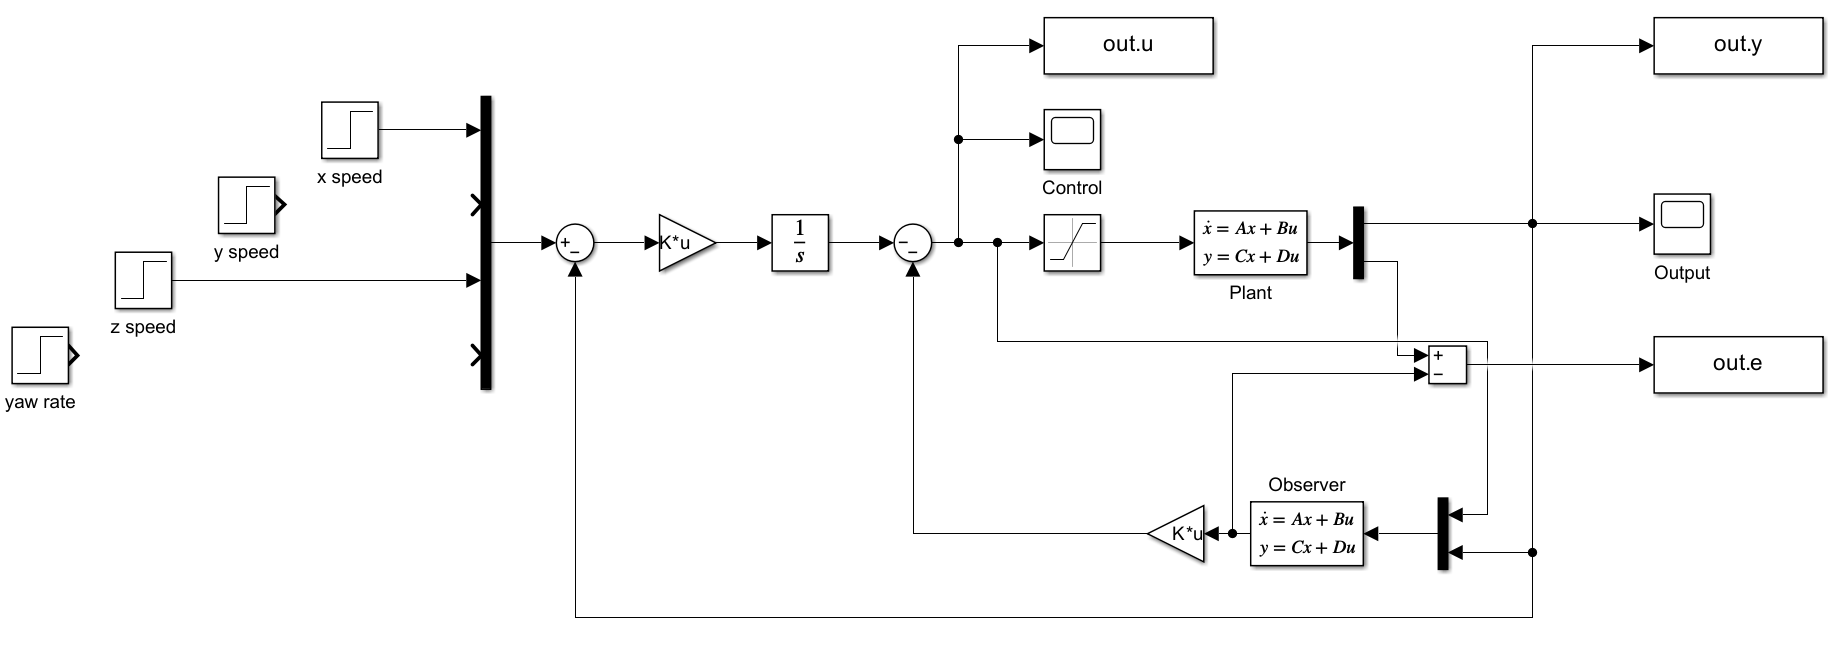

## Mixed Sensitivity Design

La tecnica del Mixed Sensitivity Design consente di tener conto anche di specifiche sulla robustezza. Si suppone che l'impianto sia affetto da incertezza moltiplicativa: $G_{\textrm{real}} =G_t \cdot G$ dove $G_t =\left\lbrack \begin{array}{cccc}
k_1 e^{-\theta_1 s}  &  &  & \\
 & k_2 e^{-\theta_2 s}  &  & \\
 &  & k_3 e^{-\theta_3 s}  & \\
 &  &  & k_4 e^{-\theta_4 s} 
\end{array}\right\rbrack$: l'impianto reale presenta un'incertezza in uscita su ogni canale che nel caso peggiore è del $\pm 10%$ sul guadagno, ed un ritardo di tempo di $10\;\textrm{ms}$.

Il comando **mixsyn** cerca il regolatore $R$ che minimizza la norma $H_{\infty }$ della matrice $G_{\textrm{zw}} =\left\lbrack \begin{array}{c}
W_S \cdot S\\
W_T \cdot T\\
W_K \cdot R\;S
\end{array}\right\rbrack$ dove $T$ ed $S$ sono rispettivamente le funzioni di sensitività complementare e diretta. Le matrici $W_S ,W_T \;e\;W_K$ sono delle matrici di peso che consentono di scegliere in quale banda andare a minimizzare maggiormente la matrice che moltiplicano.

### Scelta della Wt

Posto $G_t \left(s\right)=\left(I+\Delta \left(s\right)\right)$ si dimostra applicando il teorema del piccolo guadagno che il sistema è robusto se $||W_T \cdot \;T||_{\infty } <1$. La matrice di peso $W_T$ deve maggiorare l'incertezza $\Delta$ per ogni frequenza. Trattandosi in generale di una condizione sufficiente molto restrittiva, sono tollerate piccole bande di frequenze in cui la maggiorazione non è perfetta.

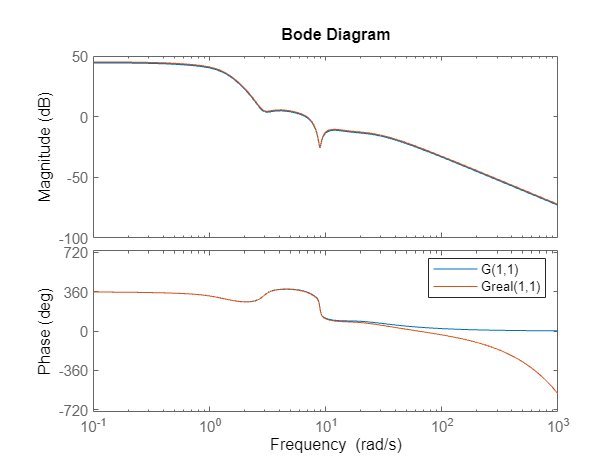

delay = 0.01;

Gt = ss([],[],[],diag([1.1 1.1 1.1 1.1]));
Gt.OutputDelay=delay*ones(1,4);
Greal = Gt*sys;
bode(G(1,1),Greal(1,1))
legend("G(1,1)","Greal(1,1)")

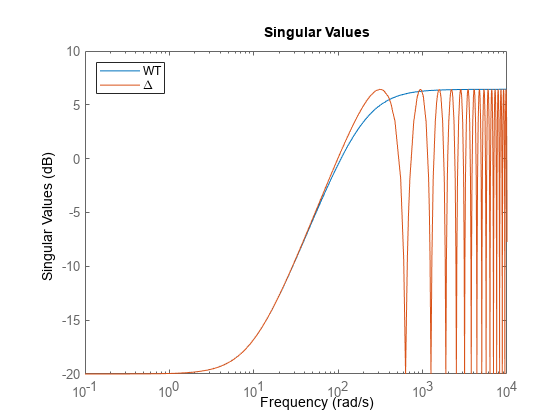

Delta=(eye(4)-Gt);
WT =  (1 - 1.1*(1-s*delay/2)/(1+s*delay/2)).*eye(4);
sigma(WT,Delta)
legend('WT','\Delta','Location','northwest')

### Scelta della Ws e Wk

Le matrici $W_S$ e $W_K$ vengono scelte per tentativi. La matrice di peso della sensitività diretta la si sceglie grande dove si vuole $T$ grande: la si vuole unitaria nella banda passante desiderata. Per avere inseguimento del riferimento a gradino vengono messi dei poli a bassissima frequenza che forzano la presenza di un integratore nella funzione di anello.

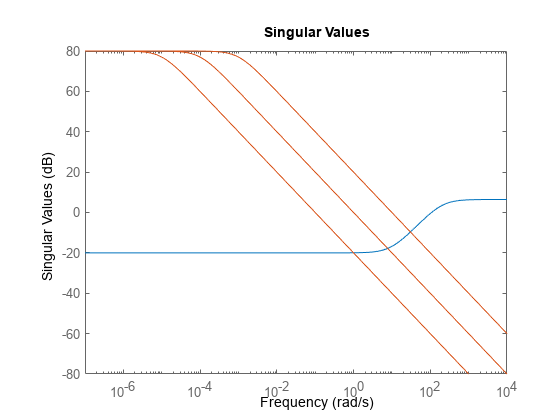

WS = tf(zeros(4));
WS(1,1) = 1e4/(1+s/1e-4);
WS(2,2) = 1e4/(1+s/1e-3);
WS(3,3) = 1e4/(1+s/1e-5);
WS(4,4) = 1e4/(1+s/1e-5);
sigma(WT,WS)

La matrice $W_K$ serve a pesare la grandezza di controllo. Per migliorare ulteriormente il controllo negli istanti iniziali si è scelto di filtrare i riferimenti di velocità $u,v,w$ attraverso opportuni filtri del primo ordine.

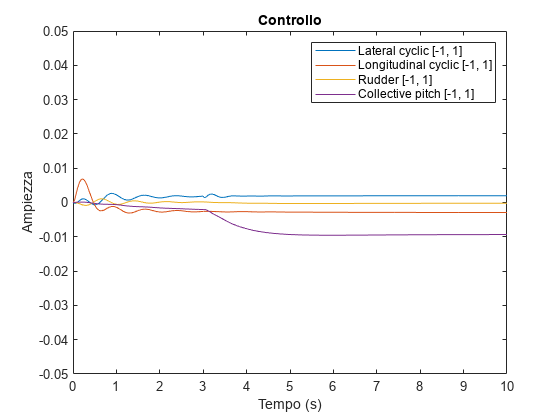

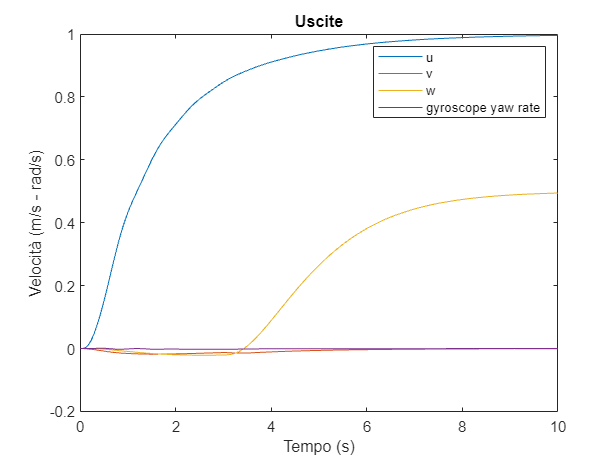

WK = tf(1e0.*diag([1 1 1 1]).*0.5);
[K_inf,CL,GAM,INFO] = mixsyn(sys,WS,WK,WT);

out_hinf = sim('H_inf_sim.slx');
plotyu(out_hinf,'ulim',[-0.05,0.05],'ylegend',outputs,'ulegend',inputs,'un',1:4,'yn',1:4)

Le specifiche sono ampiamente rispettate con un maggior disaccoppiamento fra i canali rispetto al progetto con assegnamento degli autovalori.

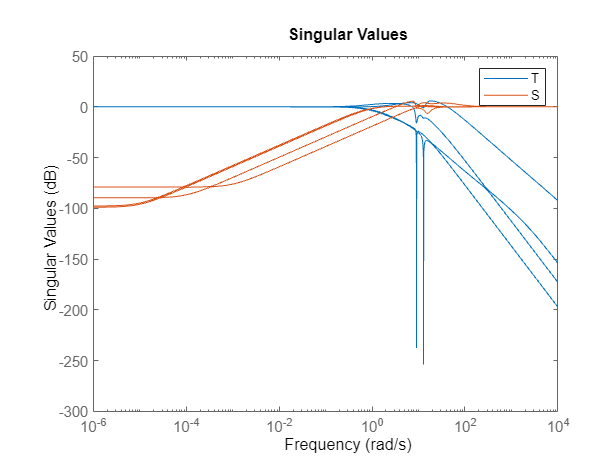

L = G*K_inf;
S = feedback(eye(4),L);
T = feedback(L,eye(4));
sigma(T,S)
legend('T','S')

Inoltre, i valori singolari di $W_T \cdot T$ sono sempre al di sotto dell'asse $0\textrm{db}$, quindi il sistema è robusto. Ciò trova riscontro nella simulazione sul sistema reale.

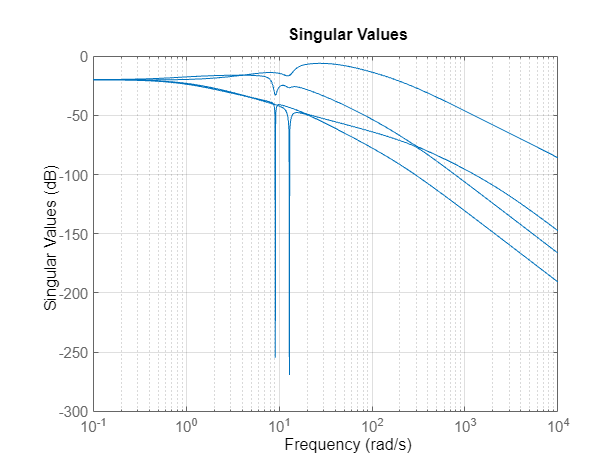

sigma(WT*T),grid

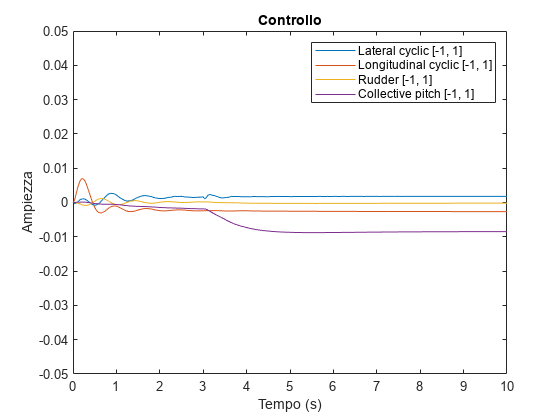

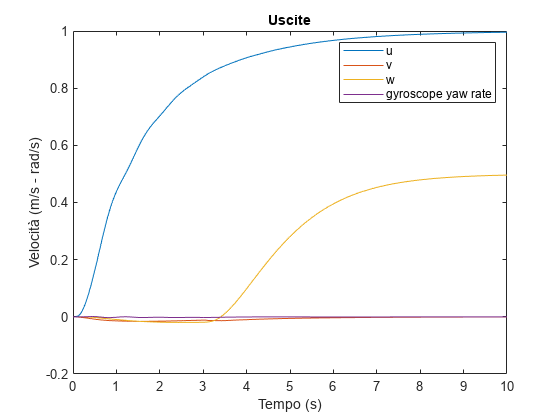

plotyu(out_hinf,'ulim',[-0.05,0.05],'ylegend',outputs,'ulegend',inputs,'un',5:8,'yn',5:8)

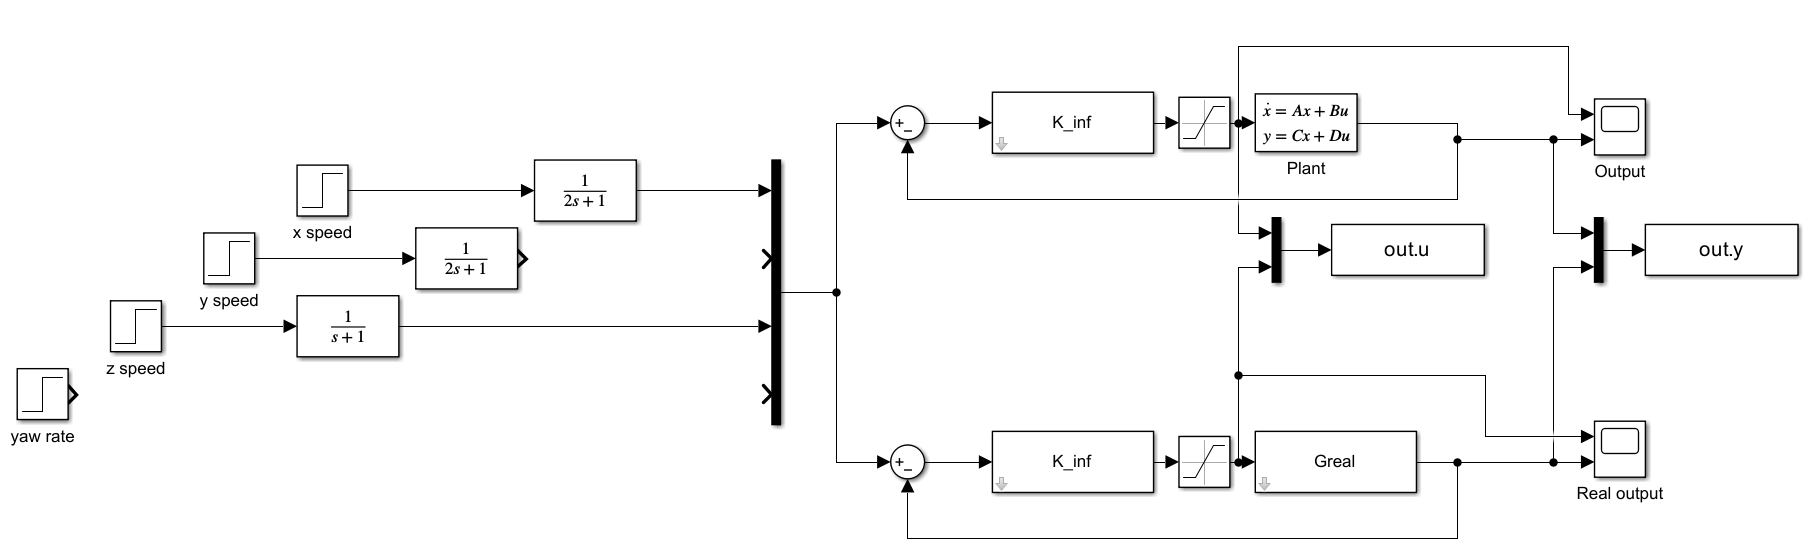

## Controllo LQ

Il controllo ottimo LQ consiste nel trovare la matrice $K$ della retroazione di stato che minimizza la funzione obiettivo $\int_0^{+\infty \;} x^T Q\;x+u^T R\;u\;\textrm{dt}$. Le matrici $Q$ ed $R$ penalizzano rispettivamente alti valori dello stato e degli ingressi di controllo. I valori sono scelti procedendo per tentativi fino ad ottenere la risposta con le caratteristiche desiderate. Dato che si vuole errore a regime nullo, il comando **lqr** viene eseguito sulle matrici dell'impianto aumentato, con la presenza di 4 integratori.

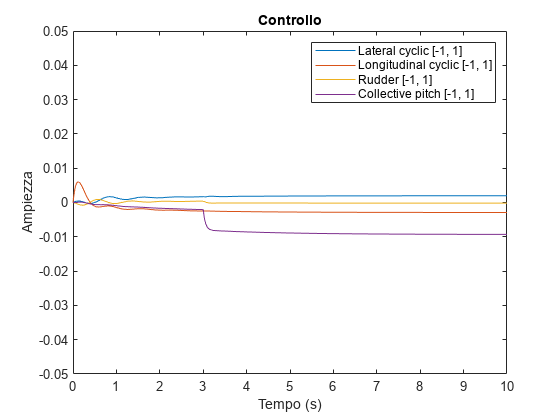

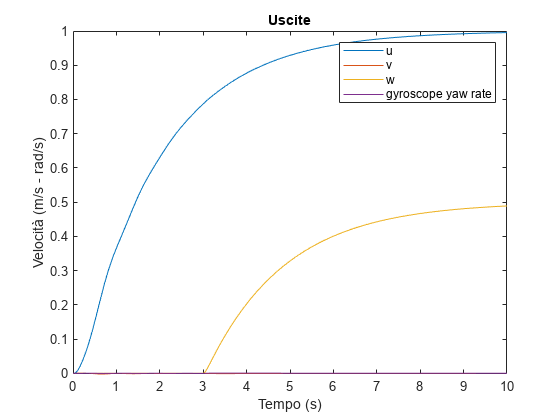

Q = diag([1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 0.3; 0.3; 0.3; 0.3]).*1;
R = diag([1; 4; 1; 1]).*5;
[K_lq, S, eig_LQ] = lqr(Aint, Bint,Q,R);
K_s_lq = K_lq(:,1:13);
K_i_lq = K_lq(:,14:17);
out_lq = sim('LQR_sim');
plotyu(out_lq,'ulim',[-0.05,0.05],'ylegend',outputs,'ulegend',inputs)

Con questa scelta delle matrici di peso, si riesce ad ottenere una risposta che rispetta la specifica sul tempo di assestamento senza sovraelongazione. Allo stesso tempo, le grandezze di controllo sono molto contenute ed i canali sono fortemente disaccoppiati.

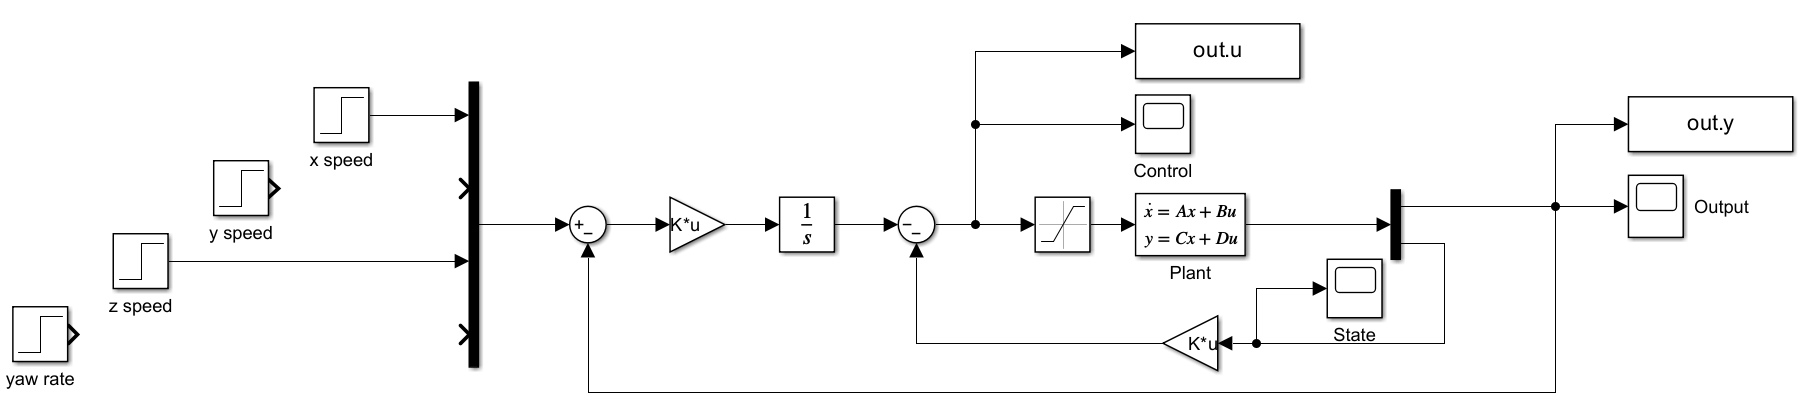

## Filtro di Kalman

Per mantenere l'ottimalità della soluzione inserendo un osservatore è necessario utilizzare un filtro di Kalman, il quale è utile anche per minimizzare la varianza dell'errore di stima nel caso in cui siano presenti rumori di processo o di misura dell'uscita. Per il principio di separazione, il progetto dell'osservatore può essere effettuato una volta completato il progetto della retroazione di stato. In particolare, è sufficiente risolvere il problema LQ al sistema duale ottenendo la matrice $L$ dell'osservatore. Ancora una volta, l'osservatore viene fatto partire con condizioni iniziali diverse da quelle effettive.

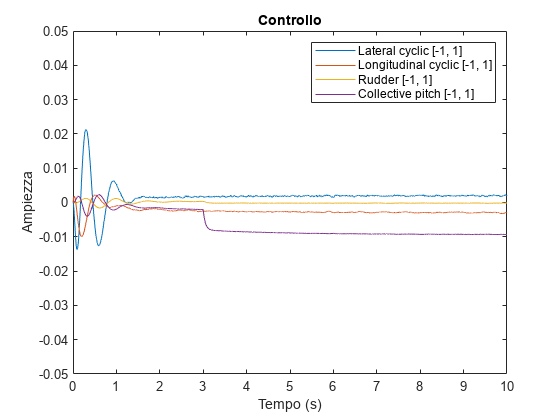

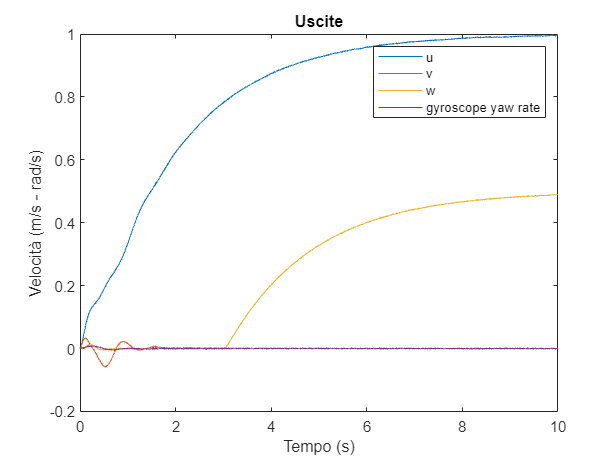

BandWidth=500;
NoisePower=1e-6/BandWidth;
Rt=eye(4)*NoisePower;
Qt=eye(13)*1e-10;

L_kalman = lqr(A',C',Qt,Rt)';
A_k = (A-L_kalman*C);
B_k = [B - L_kalman*D, L_kalman];
C_k = eye(13);
D_k = zeros(13,8);

x0_obs = rand(13,1)*0.005-0.0025;
out_lqg = sim('LQG_sim');
plotyu(out_lqg,'ulim',[-0.05,0.05],'ylegend',outputs,'ulegend',inputs)

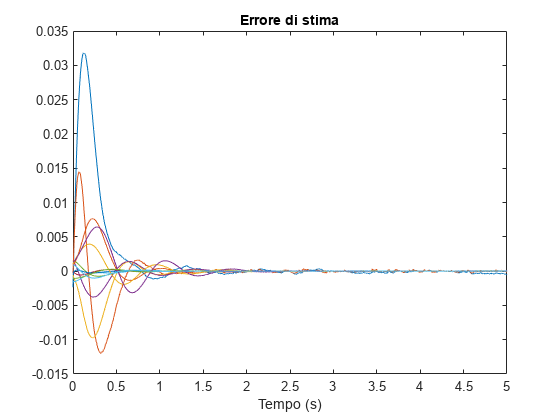

plot(out_lqg.e.time,out_lqg.e.signals.values);
title('Errore di stima')
xlabel('Tempo (s)')
xlim([0 5])